**Question 01:** A **circular tube of radius **R=0.05** m**, the flow of a viscous slag is studied under a **pressure-driven flow** condition. The viscosity of different slag samples is provided in an experimental dataset.

Using **boundary value problem (BVP) modeling**, the velocity distribution Vz and its gradient $ \frac{dv_z}{dr} $�� are analyzed across the tube radius.

**Given Parameters:**

- Pressure difference: P0=1.0 Pa (start), PL=0.1 Pa (end)

- Tube length: L=1.0 m

- Density: ρ=800 kg/m³

- Gravitational acceleration: g=9.8 m/s²

- Tube radius: R=0.05 m

- Viscosity μ varies for each slag sample

**Boundary Conditions:**

- $ \frac{dv_z}{dr} $ =0 at r =0 (No shear at the tube center)

- Vz =0 at r =R (No-slip condition at the wall)

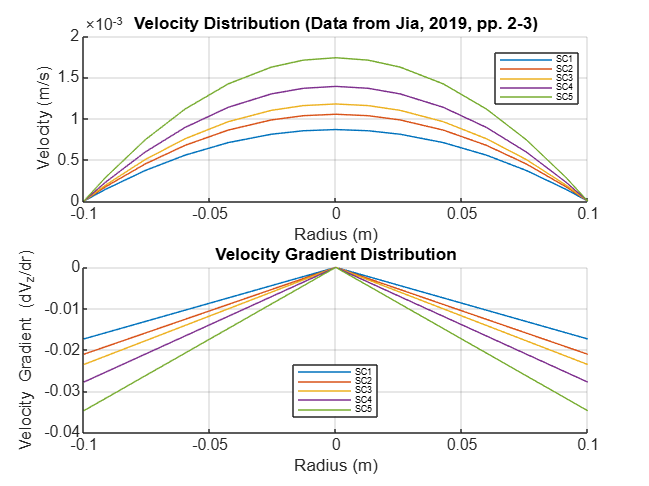

% Read the data from the Excel file
data = readtable("Jia_2019_viscosity_results.xlsx", 'VariableNamingRule', 'preserve');

% Constants
P0 = 1.0;  % Pressure at start (Pa)
PL = 0.1;  % Pressure at end (Pa)
L = 1.0;   % Length of the tube (m)
rho = 2.5 * 10^3;  % Density (kg/m^3)
g = 9.8;   % Gravitational acceleration (m/s^2)
R = 0.1;  % Radius of the tube (m)

% Prepare the plot
figure;
subplot(2, 1, 1);
hold on;
xlabel('Radius (m)');
ylabel('Velocity (m/s)');
title('Velocity Distribution (Data from Jia, 2019, pp. 2-3)');
grid on;

subplot(2, 1, 2);
hold on;
xlabel('Radius (m)');
ylabel('Velocity Gradient (dV_z/dr)');
title('Velocity Gradient Distribution');
grid on;

% Loop through each sample's viscosity data
num_samples = height(data);
rMesh = linspace(1e-6, R, 100);  % Radius values

for i = 1:num_samples
    % Extract base viscosity and sample name for the current slag
    mu = data.Viscosity(i);         % Base viscosity of the current slag
    sample_name = data.Sample{i};   % Sample name of the current slag (adjust column name if different)
    
    % Calculate the pressure gradient constant
    c = -(P0 - PL) / (L * mu);
    
    % Define the differential equation system
    % u(1) = Vz (velocity)
    % u(2) = dVz/dr (velocity gradient)
    dydr = @(r, u) [u(2); c - u(2) / r];  % [dVz/dr; d^2Vz/dr^2]
    
    % Define the boundary conditions
    % ua(2) = dVz/dr at r=0 -> 0
    % ub(1) = Vz at r=R -> 0
    bc = @(ua, ub) [ua(2);  % dVz/dr = 0 at r=0
                    ub(1)]; % Vz = 0 at r=R
    
    % Initial guess for the solution
    uInit = @(r) [0; 0]; % Initial guess for [Vz; dVz/dr]
    
    % Solve the boundary value problem
    sol = bvp4c(dydr, bc, bvpinit(rMesh, uInit));
    
    % Extract the solution
    r = sol.x;
    Vz_values = sol.y(1, :);    % Velocity values
    dVzdr_values = sol.y(2, :); % Velocity gradient values
    
    % Mirror the solution across the z-axis (extend to -R)
    r_mirrored = [-flip(r), r];
    Vz_mirrored = [flip(Vz_values), Vz_values];
    dVzdr_mirrored = [flip(dVzdr_values), dVzdr_values];
    
    % Plot the velocity distribution
    subplot(2, 1, 1);
    plot(r_mirrored, Vz_mirrored, 'DisplayName', sample_name);
    
    % Plot the velocity gradient distribution
    subplot(2, 1, 2);
    plot(r_mirrored, dVzdr_mirrored, 'DisplayName', sample_name);
end

% Finalize the plots
subplot(2, 1, 1);
legend('show', 'Location', 'best', 'FontSize', 5); % Reduce font size to 5
hold off;

subplot(2, 1, 2); 
legend('show', 'Location', 'best', 'FontSize', 5); % Reduce font size to 5
hold off;

**Question 2A:-**A thin fluid film with constant viscosity $\mu$=0.16 pa.s is spread over a rotating disk of radius  R=0.5 m, with a film thickness of  $\delta$=2.5 x 10^3 m. The disk rotates at an angular velocity of $\omega =100$ rad/s. The velocity distribution in the film is influenced by the centrifugal force, given by:

                F = ρ$\omega^2$r

where r is the radial position and ρ=800 kg/m³ is the fluid density. 

## Boundary Conditions:

- $ \frac{dv_r}{dy} $ =0 at y =0 (No shear at the fluid surface)

- $v_r$ =0 at y =δ (No-slip condition at the disk surface)

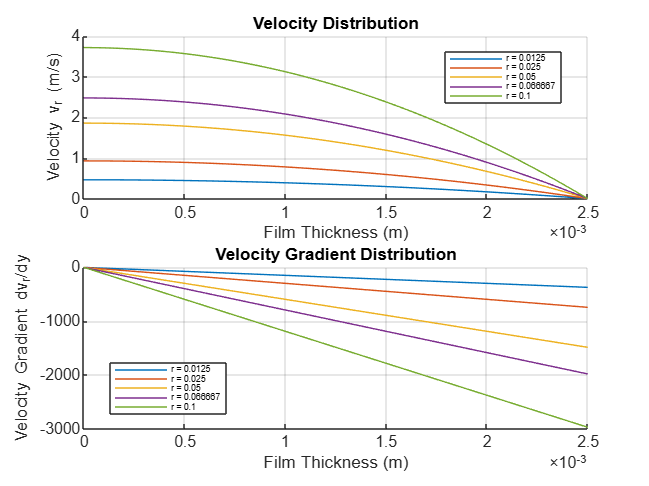

% Constants
rho = 2.5 * 10^3;          % Density (kg/m^3)
g = 9.8;                   % Gravitational acceleration (m/s^2)
delta = 2.5 * 10^-3;       % Film thickness (m)
mu = 2.1;                 % Constant viscosity (Pa.s)
omega = 100;               % Rotational speed (rad/s)
R = 0.1;                   % Disk radius (m)

% Define radial positions
r_values = [R/8, R/4, R/2, 2*R/3, R];
num_samples = length(r_values);

yMesh = linspace(0, delta, 100);  % Film thickness values

% Prepare the plot
figure;
subplot(2, 1, 1);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity v_r (m/s)');
title('Velocity Distribution');
grid on;

subplot(2, 1, 2);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity Gradient dv_r/dy');
title('Velocity Gradient Distribution');
grid on;

% Loop through each radial position
for i = 1:num_samples
    r = r_values(i);
    C = (rho * omega^2 * r); % Compute the coefficient
    
    % Define the differential equation system
    dydx = @(y, u) [u(2); -C/mu];   % [du/dy; d^2u/dy^2]
    
    % Define the boundary conditions
    bc = @(ua, ub) [ua(2); ub(1)]; % du/dy = 0 at y=0, u = 0 at y=delta
    
    % Initial guess for the solution
    uInit = @(y) [0; 0];
    
    % Solve the boundary value problem
    sol = bvp4c(dydx, bc, bvpinit(yMesh, uInit));
    
    % Extract the solution
    y = sol.x;
    v_r = sol.y(1, :);   % Velocity values
    dvrdy = sol.y(2, :); % Velocity gradient values
    
    % Plot velocity distribution
    subplot(2, 1, 1);
    plot(y, v_r, 'DisplayName', ['r = ', num2str(r)]);
    
    % Plot velocity gradient distribution
    subplot(2, 1, 2);
    plot(y, dvrdy, 'DisplayName', ['r = ', num2str(r)]);
end

% Finalize the plots
subplot(2, 1, 1);
legend('show', 'Location', 'best', 'FontSize', 5);
hold off;

subplot(2, 1, 2);
legend('show', 'Location', 'best', 'FontSize', 5);
hold off;

**Question 2B:-  Velocity Distribution for Different Rotational Speeds (ω)**

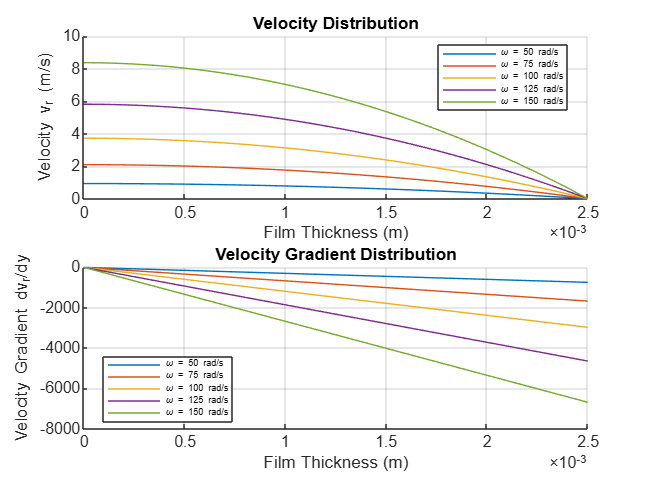

% Constants
rho = 2.5 * 10^3;          % Density (kg/m^3)
g = 9.8;                   % Gravitational acceleration (m/s^2)
delta = 2.5 * 10^-3;       % Film thickness (m)
mu = 2.1;                 % Constant viscosity (Pa.s)
R = 0.1;                   % Disk radius (m)

% Define rotational speeds
omega_values = [50, 75, 100, 125, 150]; 
num_samples = length(omega_values);

yMesh = linspace(0, delta, 100);  % Film thickness values

% Prepare the plot
figure;
subplot(2, 1, 1);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity v_r (m/s)');
title('Velocity Distribution');
grid on;

subplot(2, 1, 2);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity Gradient dv_r/dy');
title('Velocity Gradient Distribution');
grid on;

% Loop through each rotational speed
for i = 1:num_samples
    omega = omega_values(i);
    C = (rho * omega^2 * R); % Compute the coefficient for fixed r = R
    
    % Define the differential equation system
    dydx = @(y, u) [u(2); -C/mu];   % [du/dy; d^2u/dy^2]
    
    % Define the boundary conditions
    bc = @(ua, ub) [ua(2); ub(1)]; % du/dy = 0 at y=0, u = 0 at y=delta
    
    % Initial guess for the solution
    uInit = @(y) [0; 0];
    
    % Solve the boundary value problem
    sol = bvp4c(dydx, bc, bvpinit(yMesh, uInit));
    
    % Extract the solution
    y = sol.x;
    v_r = sol.y(1, :);   % Velocity values
    dvrdy = sol.y(2, :); % Velocity gradient values
    
    % Plot velocity distribution
    subplot(2, 1, 1);
    plot(y, v_r, 'DisplayName', ['\omega = ', num2str(omega), ' rad/s']);
    
    % Plot velocity gradient distribution
    subplot(2, 1, 2);
    plot(y, dvrdy, 'DisplayName', ['\omega = ', num2str(omega), ' rad/s']);
end

% Finalize the plots
subplot(2, 1, 1);
legend('show', 'Location', 'best', 'FontSize', 5);
hold off;

subplot(2, 1, 2);
legend('show', 'Location', 'best', 'FontSize', 5);
hold off;

**Question 2C:-Velocity Distribution due to Variation in Viscosity**

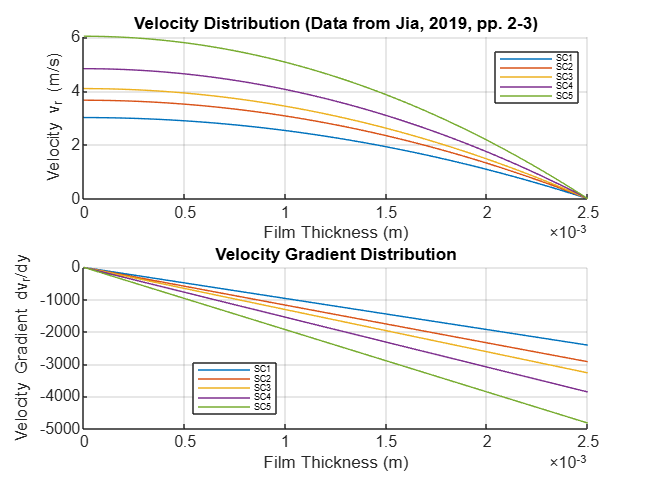

% Constants
rho = 2.5 * 10^3;          % Density (kg/m^3)
g = 9.8;                   % Gravitational acceleration (m/s^2)
delta = 2.5 * 10^-3;       % Film thickness (m)
omega = 100;               % Fixed rotational speed (rad/s)
R = 0.1;                   % Disk radius (m)

% Read viscosity values from Excel file
data = readtable("Jia_2019_viscosity_results.xlsx", 'VariableNamingRule', 'preserve');
mu_values = data.Viscosity; % Assuming the column name is 'Viscosity'

num_samples = length(mu_values);
yMesh = linspace(0, delta, 100);  % Film thickness values

% Prepare the plot
figure;
subplot(2, 1, 1);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity v_r (m/s)');
title('Velocity Distribution (Data from Jia, 2019, pp. 2-3)');
grid on;

subplot(2, 1, 2);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity Gradient dv_r/dy');
title('Velocity Gradient Distribution');
grid on;

% Loop through each viscosity value
for i = 1:num_samples

    % Extract base viscosity and sample name for the current slag
    mu = data.Viscosity(i);         % Base viscosity of the current slag
    sample_name = data.Sample{i};   % Sample name of the current slag (adjust column name if different)
    C = (rho * omega^2 * R); % Compute the coefficient for fixed omega and R
    
    % Define the differential equation system
    dydx = @(y, u) [u(2); -C/mu];   % [du/dy; d^2u/dy^2]
    
    % Define the boundary conditions
    bc = @(ua, ub) [ua(2); ub(1)]; % du/dy = 0 at y=0, u = 0 at y=delta
    
    % Initial guess for the solution
    uInit = @(y) [0; 0];
    
    % Solve the boundary value problem
    sol = bvp4c(dydx, bc, bvpinit(yMesh, uInit));
    
    % Extract the solution
    y = sol.x;
    v_r = sol.y(1, :);   % Velocity values
    dvrdy = sol.y(2, :); % Velocity gradient values
    
    % Plot velocity distribution
    subplot(2, 1, 1);
    plot(y, v_r, 'DisplayName', sample_name);
    
    % Plot velocity gradient distribution
    subplot(2, 1, 2);
    plot(y, dvrdy, 'DisplayName', sample_name);
end

% Finalize the plots
subplot(2, 1, 1);
legend('show', 'Location', 'best', 'FontSize', 5);
hold off;

subplot(2, 1, 2);
legend('show', 'Location', 'best', 'FontSize', 5);
hold off;

**Question 2D:-Velocity Distribution due to Variation in Density**

% Constants
mu = 2.1;                 % Fixed viscosity (Pa·s)
g = 9.8;                  % Gravitational acceleration (m/s^2)
delta = 2.5e-3;           % Film thickness (m)
omega = 100;              % Fixed rotational speed (rad/s)
R = 0.1;                  % Disk radius (m)

% Read density values from Excel file
data = readtable("slag_densities_Seshadri_2012.xlsx", 'VariableNamingRule', 'preserve');
rho_values = data.Density;     % Assuming the column name is 'Density'
sample_names = data.Type;      % Assuming there's a column named 'Type'

num_samples = length(rho_values);
yMesh = linspace(0, delta, 100);  % Film thickness values

% Prepare the plots
figure;

% Subplot for velocity
subplot(2, 1, 1);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity v_r (m/s)');
title('Velocity Distribution (Data from Seshadri,2012,pp. 7)');
grid on;

% Subplot for velocity gradient
subplot(2, 1, 2);
hold on;
xlabel('Film Thickness (m)');
ylabel('Velocity Gradient dv_r/dy');
title('Velocity Gradient Distribution');
grid on;

% Loop through each density value
for i = 1:num_samples
    rho = rho_values(i);            % Current density
    disp(['Solving for density: ', num2str(rho), ' kg/m^3']); % Debug info

    C = (rho * omega^2 * R);        % Coefficient for BVP

    % Define the differential equation: u'' = -C/mu
    dydx = @(y, u) [u(2); -C/mu];

    % Boundary conditions: du/dy(0) = 0, u(delta) = 0
    bc = @(ua, ub) [ua(2); ub(1)];

    % Initial guess for solution
    uInit = @(y) [0; 0];

    try
        % Solve BVP
        sol = bvp4c(dydx, bc, bvpinit(yMesh, uInit));
        y = sol.x;
        v_r = sol.y(1, :);    % Velocity
        dvrdy = sol.y(2, :);  % Velocity gradient

        % Plot velocity
        subplot(2, 1, 1);
        hold on; % Ensure hold is active
        plot(y, v_r, 'DisplayName', [num2str(rho) ' kg/m^3']);

        % Plot velocity gradient
        subplot(2, 1, 2);
        hold on;
        plot(y, dvrdy, 'DisplayName', [num2str(rho) ' kg/m^3']);

    catch ME
        warning(['Failed to solve BVP for density ', num2str(rho), ': ', ME.message]);
    end
end

Solving for density: 2.7 kg/m^3
Solving for density: 2.98 kg/m^3
Solving for density: 2.67 kg/m^3
Solving for density: NaN kg/m^3


Solving for density: NaN kg/m^3


Solving for density: NaN kg/m^3


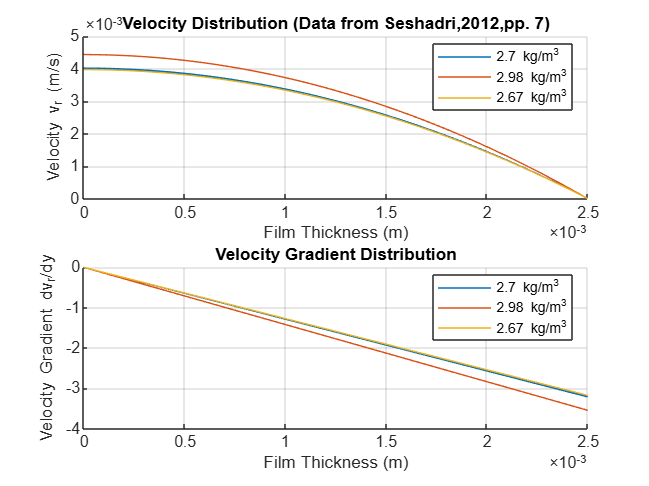


% Add legends at the end
subplot(2, 1, 1);
legend('show', 'Location', 'best', 'FontSize', 8);
hold off;

subplot(2, 1, 2);
legend('show', 'Location', 'best', 'FontSize', 8);
hold off;

Question 2E:- Calculate the diameter of the resulting slag droplets: $\[
d = 1.9 \times 1.6 \times R \left( \left( \frac{4 \rho Q}{\pi \mu R} \right)^{0.26} \cdot \left( \frac{\rho \omega^2 R^3}{\sigma} \right)^{-0.42} \cdot \left( \frac{\mu}{\sqrt{\rho \sigma R}} \right)^{0.38} \right) + 61
\]
$ where R is in µm.

% Constants
rho = 2.5 * 10^3;       % kg/m^3
delta = 2.5 * 10^-3;    % m
mu = 2.1;               % Pa·s
omega = 100;            % rad/s
R = 0.1;                % m
Vz = (2/3) * 3.72024;   % m/s
sigma = 0.45;           % N/m

% Area of film flow
A = 2 * pi * R * delta;

% Volumetric flow rate Q
Q = A * Vz;  % units: m^3/s

% Intermediate terms
term1 = (4 * rho * Q) / (pi * mu * R);
term2 = (rho * omega^2 * R^3) / sigma;
term3 = (mu / sqrt(rho * sigma * R));

% Diameter (without +61)
d = 1.9 * 1.6 * R*10^6 * (term1^0.26 * term2^-0.42 * term3^0.38)+61;  % Result in micrometers if 61 was in µm


% Display result
fprintf('Particle diameter without = %.4f µm\n', d);

Particle diameter without = 4884.1669 µm


Question 2F:- Calculation of T_cool

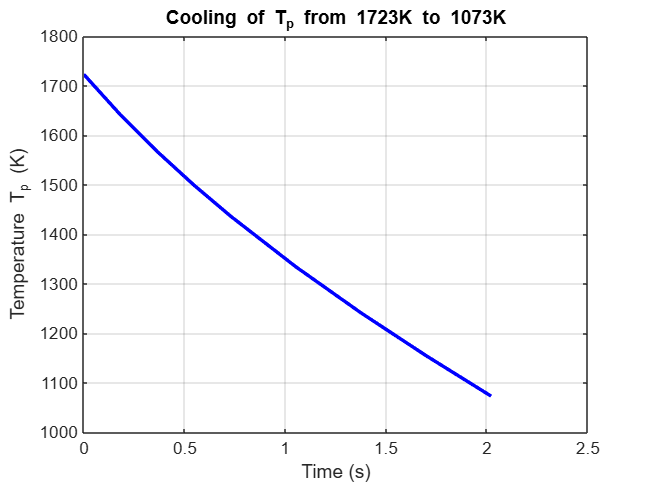

% Define the differential equation as a function handle
dTpdt = @(t, Tp) 3709.2 * (exp(-2643.68./Tp) - exp(-4165.83./Tp)) + ...
                 43.1 - 0.47*Tp - 2.01e-11*Tp.^4;

% Event function to stop when Tp reaches 1073 K
function [value, isterminal, direction] = stopEvent(t, Tp)
    value = Tp - 1073;    
    isterminal = 1;        
    direction = -1;       
end

% Set ODE options with event
options = odeset('Events', @stopEvent);

% Time span for the simulation
tspan = [0 5000];  % Extended time span

% Initial temperature (in Kelvin)
Tp0 = 1723;

% Solve the ODE
[t, Tp] = ode45(dTpdt, tspan, Tp0, options);

% Plot the result
figure;
plot(t, Tp, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Temperature T_p (K)');
title('Cooling of T_p from 1723K to 1073K');
grid on;